% Emmanuelle

% Script to fit calcium dependant fluorescence changes

%load('DataToFit.mat');
%load('Time.mat');

TStart = 1;                     % (in s)
TStartStim = 10;                % (in s)
TEndStim = 20;                  % (in s)
TStop = 59;                     % (in s)
ThresholdLevel = 0.1;           % (between 0 and 1)
Smoothing = 1;                 % number of points used for smoothing data and detecting the max

% crop recording
IdxCrop=(Time >= TStart) & (Time <= TStop);
CropedDataToFit=DataToFit(IdxCrop);
CropedTime=Time(IdxCrop);

% average baseline
IdxBaseline = (Time >= TStart) & (Time <= TStartStim);
Baseline =  DataToFit(IdxBaseline);
CaBaseline = mean(Baseline)

CaBaseline = 0.0060

% Find max of DataToFit
SmoothDataToFit = smooth(CropedDataToFit,Smoothing);
[MaxSmoothDataToFit, IdxSmoothMaxDataToFit] = max(SmoothDataToFit);
if CropedTime(IdxSmoothMaxDataToFit) >= (TEndStim - 2)
TimeMaxDataToFit = CropedTime(IdxSmoothMaxDataToFit) 
else
disp('the peak of the response was not properly detected')
end

TimeMaxDataToFit = 20.7000


% Plot smoothing with data.
figure( 'Name', 'smoothing' );
plot(Time, DataToFit, '.', 'color', 'c') ;
hold on
plot(CropedTime, SmoothDataToFit)
legend( 'data', 'smoothing', 'Location', 'NorthEast', 'Interpreter', 'none' );

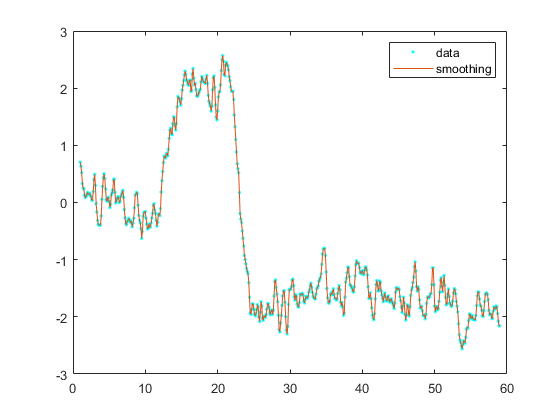

hold off


% Setup data to fit 
IndexFit1 = (CropedTime >= (TimeMaxDataToFit - 10)) & (CropedTime <= TimeMaxDataToFit);
IndexFit2 = (CropedTime > TimeMaxDataToFit) & (CropedTime <= TStop);
[xData1, yData1] = prepareCurveData( CropedTime(IndexFit1), SmoothDataToFit(IndexFit1));
[xData2, yData2] = prepareCurveData( CropedTime(IndexFit2), SmoothDataToFit(IndexFit2));

% Fit  ydata1
% Set up fittype and options.
ft1 = fittype( 'a1*(x-T1)^2 + b1*(x-T1) + c1', 'independent', 'x', 'dependent', 'y' );
opts1 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts1.Display = 'Off';
opts1.Lower = [-Inf -Inf -Inf CaBaseline];
opts1.StartPoint = [10 -1 -1 CaBaseline];
opts1.Upper = [Inf Inf Inf CaBaseline];

% Fit model to data.
[fitresult1, gof1] = fit( xData1, yData1, ft1, opts1 )

fitresult1 =      General model:
     fitresult1(x) = a1*(x-T1)^2 + b1*(x-T1) + c1
     Coefficients (with 95% confidence bounds):
       T1 =       11.57  (11.42, 11.73)
       a1 =    -0.05564  (-0.06242, -0.04886)
       b1 =       0.694  (0.6462, 0.7418)
       c1 =    0.006014  (fixed at bound)

gof1 = struct with fields:
           sse: 6.6752
       rsquare: 0.9073
           dfe: 98
    adjrsquare: 0.9055
          rmse: 0.2610


fitcoeffvals1= coeffvalues(fitresult1);

T1 = fitcoeffvals1(1)

T1 = 11.5730

a1 = fitcoeffvals1(2)

a1 = -0.0556

b1 = fitcoeffvals1(3)

b1 = 0.6940

c1 = fitcoeffvals1(4)

c1 = 0.0060



% Fit  ydata2
% Set up fittype and options.
ft2 = fittype( 'a2*(exp(-(x-b2)/T2)-1)+a3*(exp(-(x-b2)/T3)-1)+c2', 'independent', 'x', 'dependent', 'y' );
opts2 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts2.Display = 'Off';
opts2.Lower = [0 0 0 0 TimeMaxDataToFit a1*(TimeMaxDataToFit-T1)^2+b1*(TimeMaxDataToFit-T1)+c1];
opts2.StartPoint = [1 0.9 20 0.6 TimeMaxDataToFit a1*(TimeMaxDataToFit-T1)^2+b1*(TimeMaxDataToFit-T1)+c1];
opts2.Upper = [Inf Inf Inf Inf TimeMaxDataToFit a1*(TimeMaxDataToFit-T1)^2+b1*(TimeMaxDataToFit-T1)+c1];

[fitresult2, gof2] = fit( xData2, yData2, ft2, opts2 )

fitresult2 =      General model:
     fitresult2(x) = a2*(exp(-(x-b2)/T2)-1)+a3*(exp(-(x-b2)/T3)-1)+c2
     Coefficients (with 95% confidence bounds):
       T2 =        2.52  (1.92, 3.121)
       T3 =        7796  (-3.23e+07, 3.232e+07)
       a2 =       3.351  (2.887, 3.815)
       a3 =       25.25  (-1.043e+05, 1.044e+05)
       b2 =        20.7  (fixed at bound)
       c2 =       1.705  (fixed at bound)

gof2 = struct with fields:
           sse: 83.8082
       rsquare: 0.7225
           dfe: 379
    adjrsquare: 0.7203
          rmse: 0.4702


fitcoeffvals2= coeffvalues(fitresult2);

T2 = fitcoeffvals2(1)

T2 = 2.5203

T3 = fitcoeffvals2(2)

T3 = 7.7964e+03

a2 = fitcoeffvals2(3)

a2 = 3.3512

a3 = fitcoeffvals2(4)

a3 = 25.2521

b2 = fitcoeffvals2(5)

b2 = 20.7000

c2 = fitcoeffvals2(6)

c2 = 1.7050

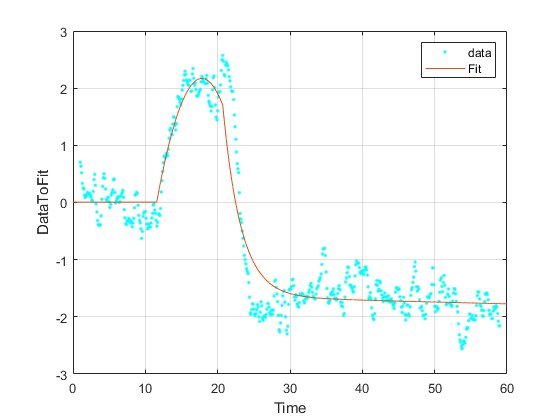

% plot and nomalize

TTime = (0:0.01:60)';
FitTTime = zeros(6001,1);

for icnt = 1:6001
    FitTTime(icnt) = FitRespRateFunction(CaBaseline, TimeMaxDataToFit, fitcoeffvals1, fitcoeffvals2, TTime(icnt));
end

% Plot fit with data.
figure( 'Name', 'CalciumDependantFluoFit' );
h = plot(Time, DataToFit, '.', 'color', 'c') ;
hold on
plot(TTime, FitTTime),
legend('data', 'Fit', 'Location', 'NorthEast');
hold off

% Label axes
xlabel( 'Time' );
ylabel( 'DataToFit');
grid on

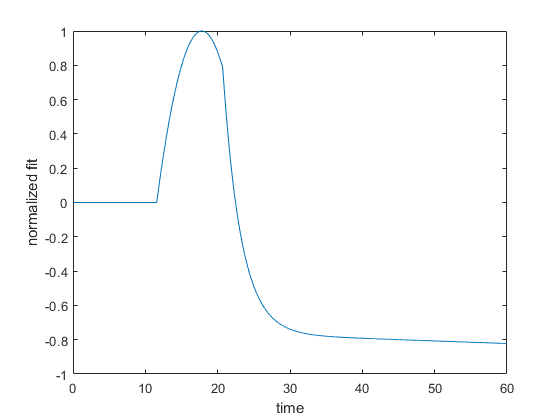

% normalized fit
[MaxFit, IdxMax] = max(FitTTime);
NormFit = (FitTTime - CaBaseline) / (MaxFit - CaBaseline);

% plot norm fit 
figure( 'Name', 'Normalized Fit' );
h2 = plot( TTime, NormFit );
% Label axes
xlabel( 'time');
ylabel( 'normalized fit');

% Time threshold calculation  

IndexBelowThreshold = (NormFit <= ThresholdLevel);
IndexBeforeMax = IndexBelowThreshold(1:IdxMax);
TimeBeforeThreshold = TTime(IndexBeforeMax);
[TimeThrehold, IdxTimeThrehold] = max(TimeBeforeThreshold);
TimeThrehold;

IndexBelowThreshold10 = (NormFit <= 0.1);
IndexBeforeMax10 = IndexBelowThreshold10(1:IdxMax);
TimeBeforeThreshold10 = TTime(IndexBeforeMax10);
[TimeThrehold10, IdxTimeThrehold10] = max(TimeBeforeThreshold10);
TimeThrehold10

TimeThrehold10 = 11.8900


IndexBelowThreshold15 = (NormFit <= 0.15);
IndexBeforeMax15 = IndexBelowThreshold15(1:IdxMax);
TimeBeforeThreshold15 = TTime(IndexBeforeMax15);
[TimeThrehold15, IdxTimeThrehold15] = max(TimeBeforeThreshold15);
TimeThrehold15

TimeThrehold15 = 12.0500


IndexBelowThreshold20 = (NormFit <= 0.2);
IndexBeforeMax20 = IndexBelowThreshold20(1:IdxMax);
TimeBeforeThreshold20 = TTime(IndexBeforeMax20);
[TimeThrehold20, IdxTimeThrehold20] = max(TimeBeforeThreshold20);
TimeThrehold20

TimeThrehold20 = 12.2300


TimeThrehold101520 = [TimeThrehold10 ; TimeThrehold15 ; TimeThrehold20];

function y = FitRespRateFunction(CaBaseline, TimeMaxDataToFit, fitcoeffvals1, fitcoeffvals2, x)
   if x <= fitcoeffvals1(1)
       y = CaBaseline; 
   elseif x <= TimeMaxDataToFit
       y = fitcoeffvals1(2)*(x-fitcoeffvals1(1))^2 + fitcoeffvals1(3)*(x-fitcoeffvals1(1)) + fitcoeffvals1(4); 
   else
       y = fitcoeffvals2(3)*(exp(-(x-TimeMaxDataToFit)/fitcoeffvals2(1))-1) + ...
       fitcoeffvals2(4)*(exp(-(x-TimeMaxDataToFit)/fitcoeffvals2(2))-1) + fitcoeffvals2(6);
   end
end